# Cvičení 1 - Bonus - B2M31AEDA

## 1) Fibonacciho posloupnost

Fibonacciho posloupnost vypadá následovně:


$$\begin{array}{l}
F=0,1,1,2,3,5,\ldots\;\\
F_0 =0,F_1 =1,F_n =F_{n-1} +F_{n-2} \;,\ldots
\end{array}$$


Napište funkci, která bude brát jediný, libovolný, kladný, celočíselný vstup `N`, a bude generovat na výstupu příslušnou `N`-tou hodnotu Fibonacciho posloupnosti.

% Vaše funkce pro výpočet N-tého prvku Fibonacciho posloupnosti
function Fn = fibonacci_n(N)
    if N == 0
        Fn = 0;
        return;
    elseif N == 1
        Fn = 1;
        return;
    end

    A = [0 1; 1 1]^(N);
    res = A * [0; 1];

    Fn = res(1);

end

Vydělením dvou sousedících prvků Fibonacciho posloupnosti pro N >> 1 (např. 1000), vám vyjde přibližná hodnota Zlatého řezu 𝜑.


$$\hat{\textrm{𝜑}} =\frac{F_N }{F_{N-1} };N>1$$


Čím větší bude `N`, tím bude hodnota blíže skutečné hodnotě 𝜑. Ilustrujte pomocí grafu, jak se výpočet zlatého řezu pomocí Fibonacciho čísel blíží jeho skutečné hodnotě. Vyneste do grafu hodnoty aproximací pro tolik `N`, kolik uznáte za vhodné (dokud se hodnota dostatečně nepřiblíží) a konstantní čáru reprezentující skutečnou hodnotu. Nezapomeňte popsat osy, aktivovat mřížku, dodat legendu atd.

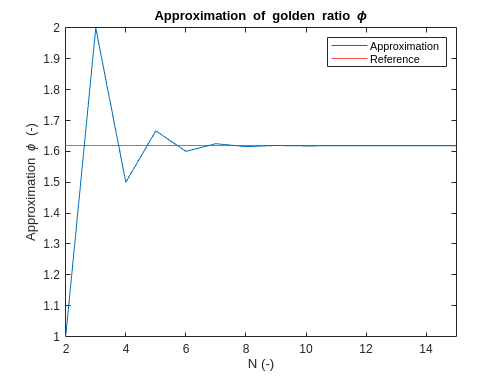

% Váš výpočet odhadu zlatého řezu pro zvyšující se N:

A = 2:15;

B = arrayfun(@fibonacci_n, A);


C = arrayfun(@fibonacci_n, A-1);

phi = B./C;

% Vykreslení závislosti odhadu 𝜑 na rostoucím N, včetně horizontální čáry
% reprezentující skutečnou hodnotu 𝜑:
% Graf dobře popište! (title, grid, xlabel, ylabel, legend)

plot(A,phi);
yline(1.618033988749, 'r');
title("Approximation of golden ratio \phi")
xlabel("N (-)")
ylabel("Approximation \phi (-)")
xlim([2 15])
legend("Approximation", "Reference")



#### Otázky:

- Slovy napište minimálně 3 případy, kde se Fibonacciho posloupnost vyskytuje v přírodě.

- Uspořádání větví na stromě

- Pozice listenů borové šišky

- graf dědičnosti genů včel

## 2) Pascalova matice

Napište funkci, která bude generovat Pascalovu matici. Funkce bude mít jeden celočíselný, kladný vstup `N`, a na výstupu bude generovat matici `P` o velikosti `N×N`, která bude symetrická a bude obsahovat hodnoty binomiálních koeficientů (více info v návodu ke cvičení).

Matice bude iniciovaná jako matice jedniček, a dále se budou hodnoty matice vypočítávat tak, aby každý prvek byl dán součtem prvků které jsou o jeden řádek výše a jeden sloupec vlevo:


$$P\left(i,j\right)=P\left(i-1,j\right)+P\left(i,j-1\right)\;;1\le i,j\le N$$


% Vaše funkce pro výpočet Pascalovy matice
% Inicializaci proveďte pomocí funkce ones, tedy ones(N)
function pM = pascalMatrix(N)

           1           1           1           1           1           1           1           1           1           1
           1           2           3           4           5           6           7           8           9          10
           1           3           6          10          15          21          28          36          45          55
           1           4          10          20          35          56          84         120         165         220
           1           5          15          35          70         126         210         330         495         715
           1           6          21          56         126         252         462         792        1287        2002
           1           7          28          84         210         462         924        1716        3003        5005
           1           8          36         120         330         792        1716        3432        6435       11440
           1           9        

    pM = ones(N);
    for i = 1:N
        for j = 1:N
            if i==1 && j==1
                continue
            end

            res = 0;
            if i > 1
                res = res + pM(i-1, j);
            end

            if j > 1
                res = res + pM(i, j-1);
            end

            pM(i,j) = res;
        end
    end            
end
% Nezapomeňte zobrazit jak vypadá vaše matice např. pro N = 10, tedy např:
% disp(pascalMatrix(10))

disp(pascalMatrix(10))

#### Otázky:

- Slovy odpovězte, jakým způsobem byste mohli z Pascalovy matice získat čísla Fibonacciho posloupnosti.

- Suma jednotlivý vedlejších diagonál dává fibonacciho sekvenci

## 3) Mandelbrotova množina

Pomocí návodu si naprogramujte výpočet Mandelbrotovy množiny a zobrazte si jí. Postup naleznete v návodu ke cvičení.

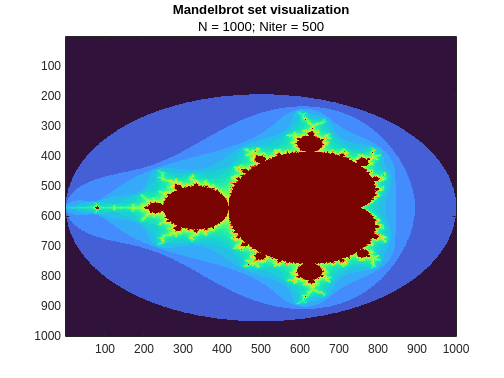

% Zde naprogramujte generování mandelbrotovy množiny o velikosti N, s
% počtem iterací Niter (obě hodnoty zvolte):
N = 1000;
Niter = 500;

x = ones(N, 1)*linspace(-2, 1, N);
y = (ones(N,1)*linspace(-2,1.5,N))';

z0 = x+1i*y;
z=z0;


mandelbrot = ones(N);

for a = 1:Niter
    z = z.*z + z0;

    in = abs(z) <= 2;

    mandelbrot = mandelbrot + in;
end

mandelbrot = log(mandelbrot);
% Hotovou množinu vykreslete funkcí imagesc. Nezapomeňte popsat osy a v
% titulku uvést vaše zvolené hodnoty N a Niter!
figure("Name","My Mandelbrot Set Visualization")
imagesc(mandelbrot)
title("Mandelbrot set visualization")
subtitle(sprintf("N = %d; Niter = %d", N, Niter))
% colormap jet
colormap("turbo")